En este ejemplo se desarrolla un ejercicio para reconocer el sesgo de un estimador.

En el caso concreto se pretende estimar la varianza de una distribución de probabilidad a partir de un conjunto de datos

Se inicia por generar los datos

m=1; % valor real de la media
s=1; % valore real de la varianza
N=4000;
P=3;
%Generando observaciones
x=normrnd(m,sqrt(s),N,P);

Se procede a calcular la estimación de la media muestral del conjunto de datos y se grafica el histograma de los datos

%Calculando estimador de media muestral
m_h=mean(x,2);
media=mean(m_h)

media = 0.9951

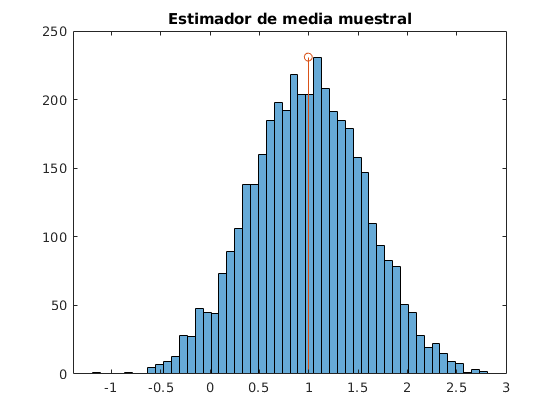

%Histograma de estimador de media muestral
figure('Name','Estimador de media muestral')
h1=histogram(m_h,50);
hold on
stem(mean(m_h),max(h1.Values))
hold off
title('Estimador de media muestral')

Observe la marca roja, esta indica el valor estimado. ¿Qué indica la altura de cada bin (barra)?.

Ahora se obtendrá el valor estimado de la varianza usando un estimador sesgado

%Estimador de varianza sesgado
s_b=var(x,1,2);
var_sesgo=mean(s_b)

var_sesgo = 0.6657

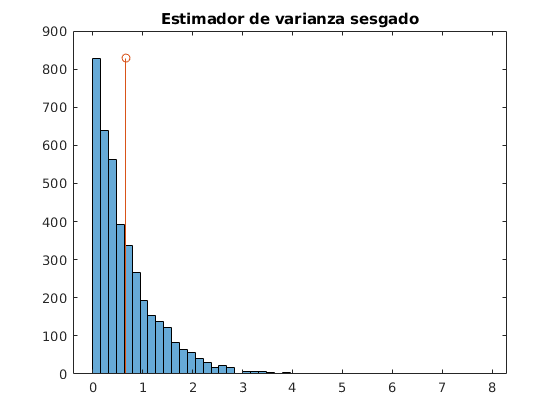

%Histograma de varianza sesgado
figure('Name','Estimador de varianza sesgado')
h2=histogram(s_b,50);
hold on
stem(mean(s_b),max(h2.Values))
hold off
title('Estimador de varianza sesgado')

Al igual que antes la marca roja indica el valor estimado. ¿Que tan alejado está del valor real?, ¿Por qué el histograma tiene esa forma?

Ahora se utilizará el estimador sin sesgo

%Estimador de varianza insesgado
s_u=var(x,0,2);
var_unses=mean(s_u)

var_unses = 0.9986

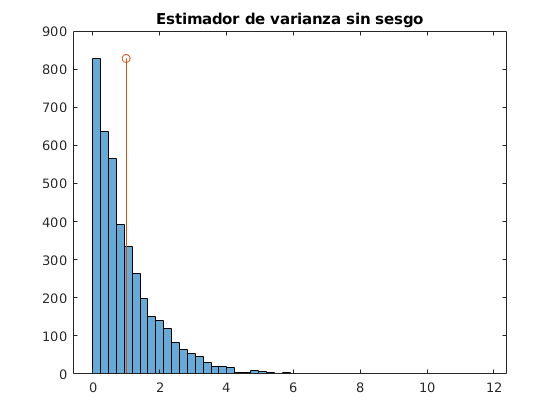

%Histograma de varianza sin sesgo
figure('Name','Estimador de varianza sin sesgo')
h3=histogram(s_u,50);
hold on
stem(mean(s_u),max(h3.Values))
hold off
title('Estimador de varianza sin sesgo')

¿Cómo cosnidera el resultado de este nuevo estimador?